We are going to average the frames, so that we can have the background from the video

v = VideoReader("Turkey Video.mp4");

frameSum = im2double(read(v, 1));

for idx = 2:v.NumFrames
    frameSum = frameSum + im2double(read(v, idx));
end

aveFrame = frameSum / v.NumFrames;

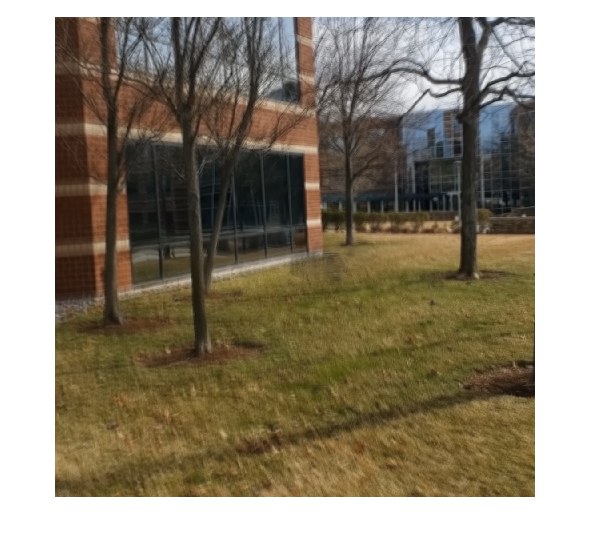

imshow(aveFrame)

I wil subract the absolute values of background from frame, so that I can only have the object inside the video

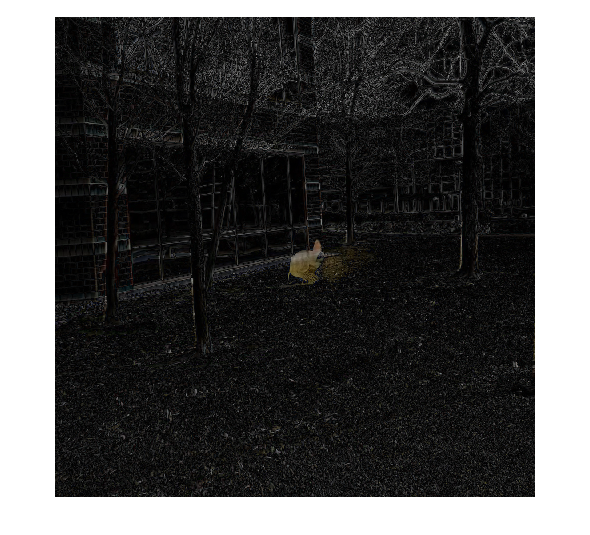

frame = read(v, 290);
frame = im2double(frame);

background = aveFrame;

frameDiff = abs(frame - background);

imshow(frameDiff)


bw = segmentTurkey(frameDiff); % This function is up to you based on your segmentation approaches

Unrecognized function or variable 'segmentTurkey'.


props = regionprops("table", bw, "BoundingBox");
turkeyBoxed = insertShape(frame, "rectangle", props.BoundingBox, "LineWidth", 3, "ShapeColor","green");

imshow(bw)

% Now apply the loop wrapper around this code and do this for all the
% frames in the video and create output video